# **Introductory script illustrating how to compute cone mosaic excitation responses to an ISETBio scene**

***This tutorial generates an ISETBio scene representing a Gabor stimulus as realized on a particular display, passes this scene through the default human optics, and computes cone mosaic excitation responses.***

#### **See also**: 

- `t_sceneForStimulusOnDisplay.mlx`  (more info on scene generation)

*Copyright: Nicolas P. Cottaris,  ISETBio Team,, 2018*

# OUTLINE

 **   Step 1.** Create a presentation display and a Gabor stimulus realized on that display

 **   Step 2.** Compute the optical image using wavefront-aberration based optics

   ** Step 3.** Create a cone mosaic object and compute its isomerization response to the optical image for a 20 msec presentation

# **Step 1.** Create a presentation display and a Gabor stimulus realized on that display

We employ an existing display specification, here an Apple LCD display and some typical params for a Gabor stimulus.

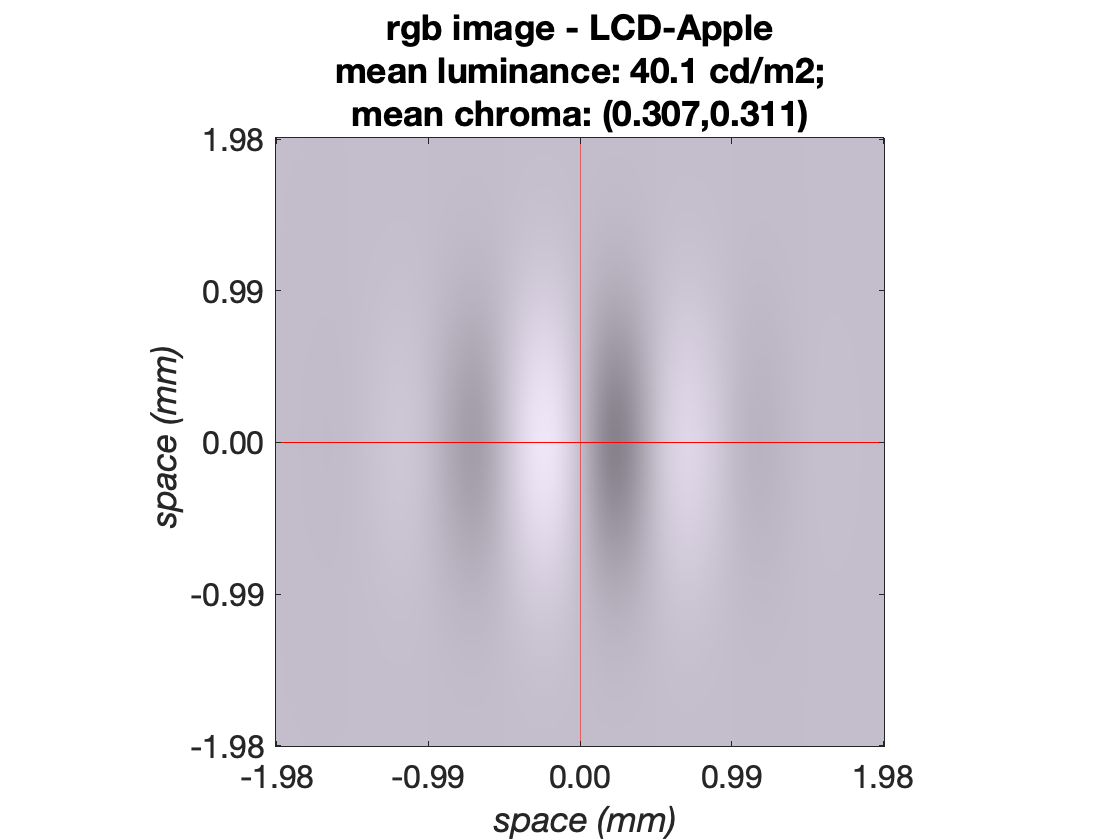

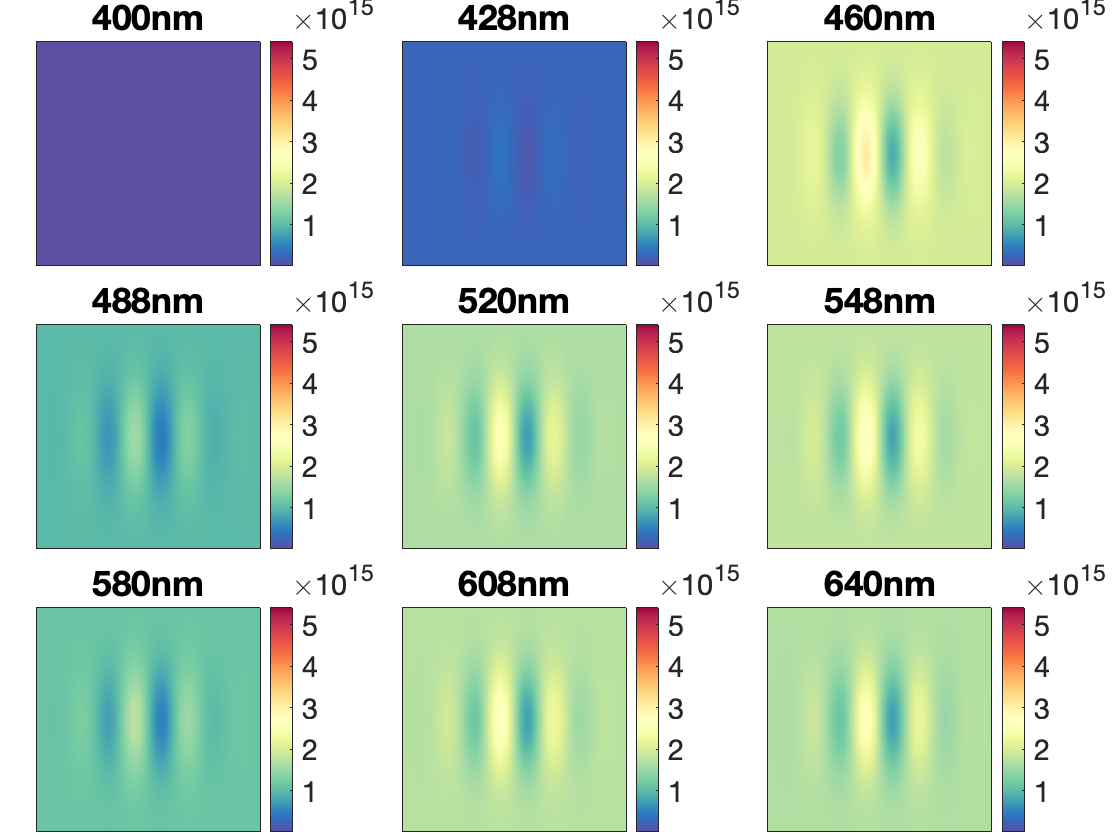

%% Create presentation display
presentationDisplay = displayCreate('LCD-Apple', 'viewing distance', 0.57);

%% parameter struct for a Gabor stimulus 
stimParams = struct(...
    'spatialFrequencyCyclesPerDeg', 10, ... % 10 cycles/deg
    'orientationDegs', 0, ...               % 45 degrees
    'phaseDegs', 90, ...                    % spatial phase degrees
    'sizeDegs', 0.4, ...                    % 0.x4 x 0.4 size
    'sigmaDegs', 0.2/3, ...                 % sigma of Gaussian envelope
    'contrast', 0.6,...                     % 0.6 Michelson contrast
    'meanLuminanceCdPerM2', 40 ...          % 40 cd/m2 mean luminance
    );

% Generate a scene representing the Gabor stimulus with the above params as
% realized on the presentationDisplay
realizedStimulusScene = generateGaborScene(stimParams,...
    'presentationDisplay', presentationDisplay);

% Visualize different aspects of the generated scene
visualizeScene(realizedStimulusScene);

# **Step 2.** Compute the optical image using wavefront-aberration based optics

We employ the default human optics model which is based on average Zernike coefficiencts from 200 human subjects. The scene is passed through the optics model to compute the retinal image.

### Step 2.1 Generate the default human optics model

Also visualize the PSF and OTF at the in-focus wavelength (550nm), a short-wavelength (450nm), and a long-wavelength (650nm)

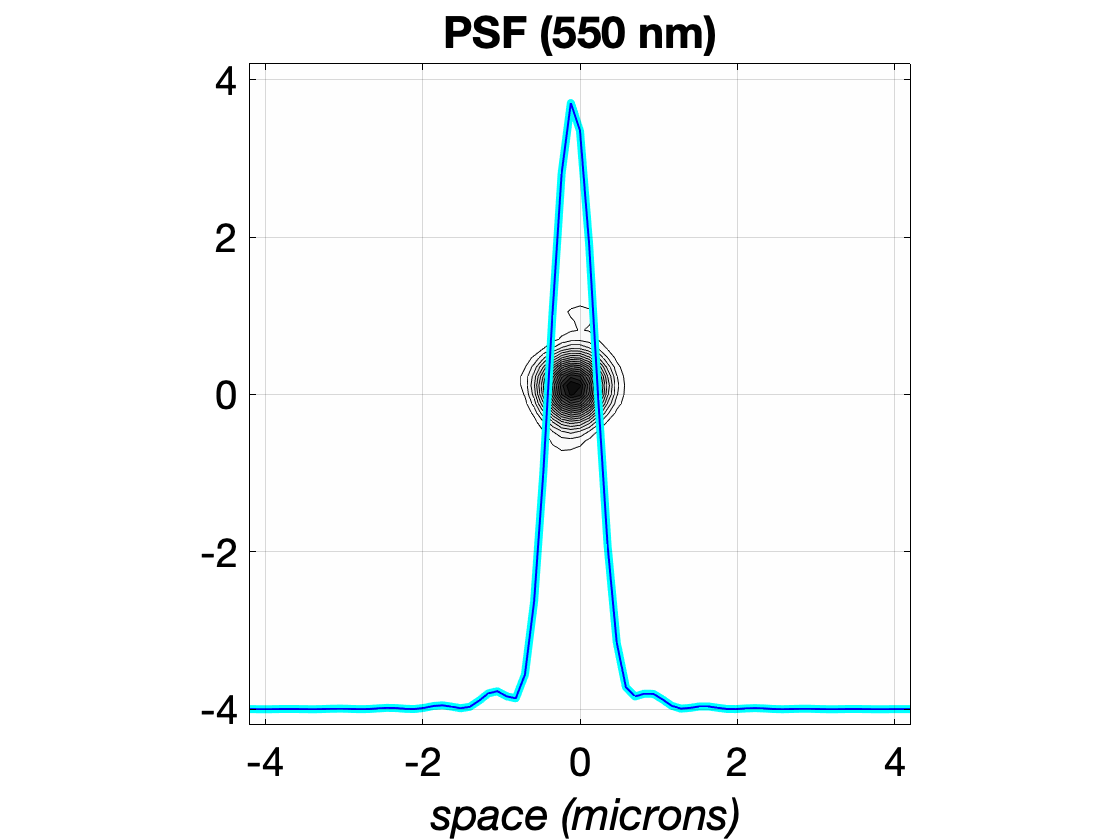

%% Generate wavefront-aberration derived human optics
theOI = oiCreate('wvf human');

% Visualize the PSFs and OTFs
visualizedSpatialSupportArcMin = 8;
visualizedSpatialSfrequencyCPD = 120;

% Visualize the PSF at 550 (in-focus) and at 500 nm
visualizePSF(theOI, 550, visualizedSpatialSupportArcMin);

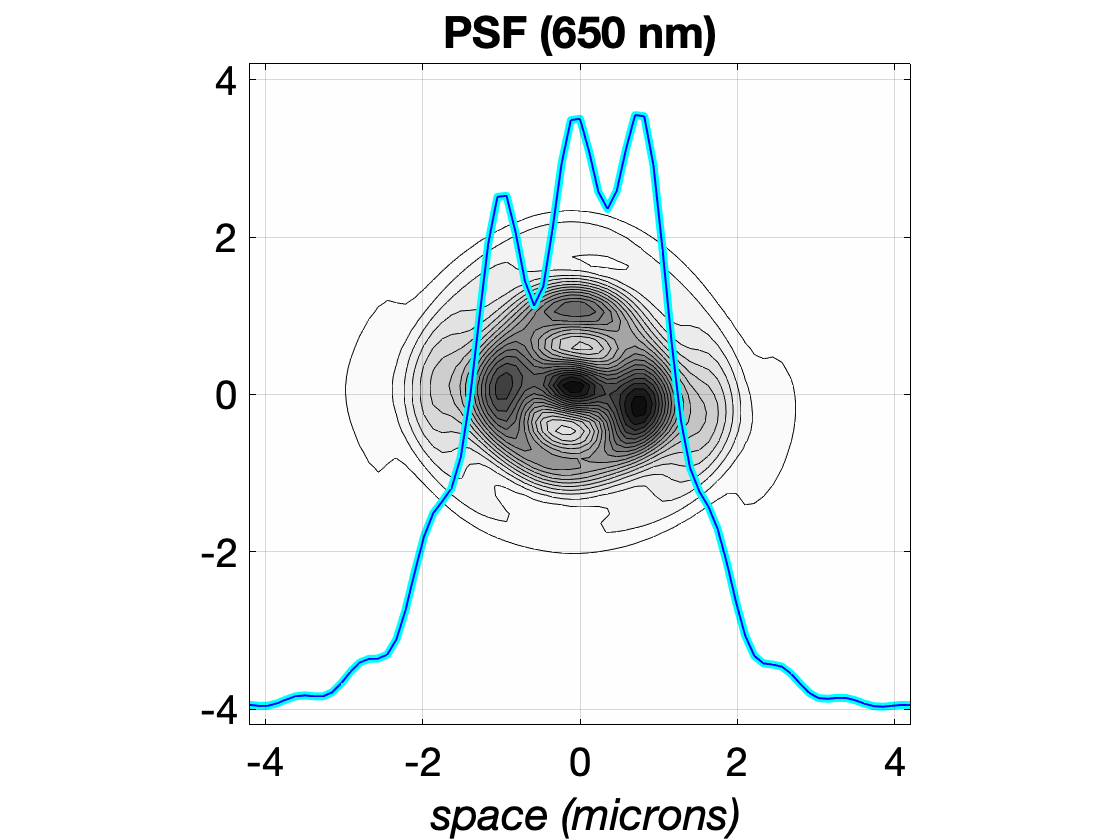

visualizePSF(theOI, 500, visualizedSpatialSupportArcMin);

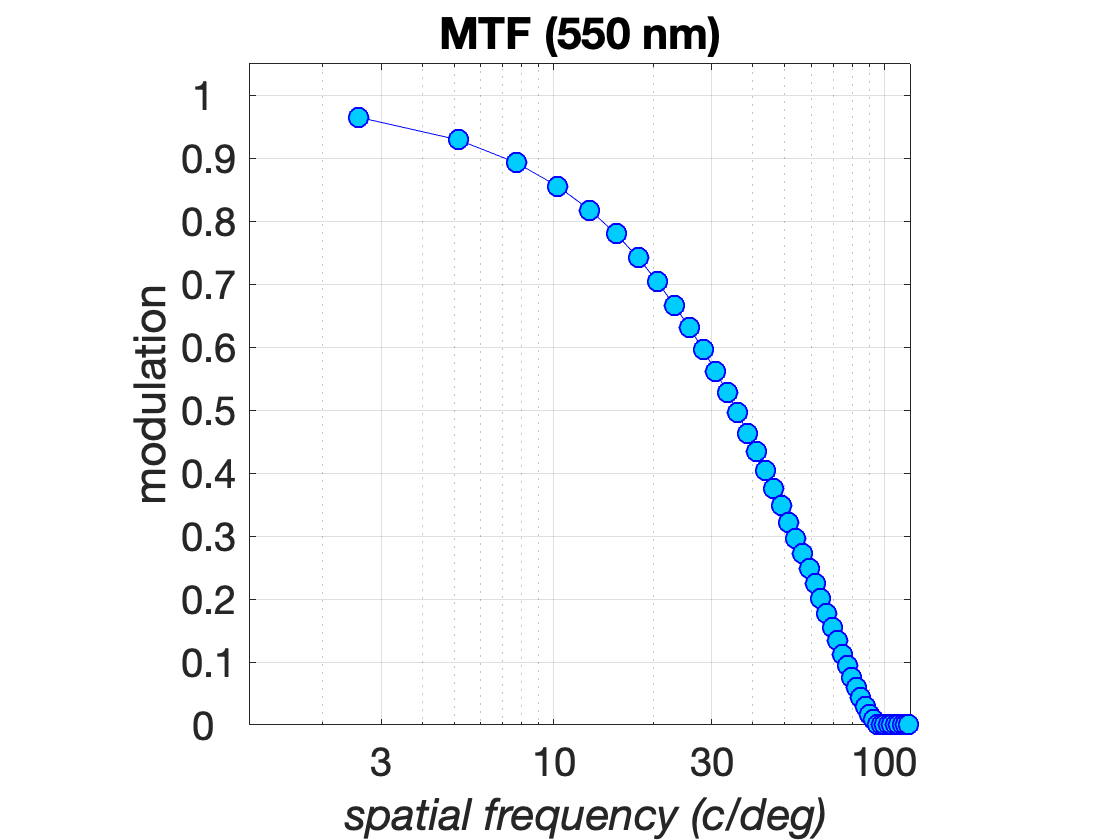


% Visualize the OTF at 550 (in-focus) and at 500 nm
visualizeOTF(theOI, 550, visualizedSpatialSfrequencyCPD);

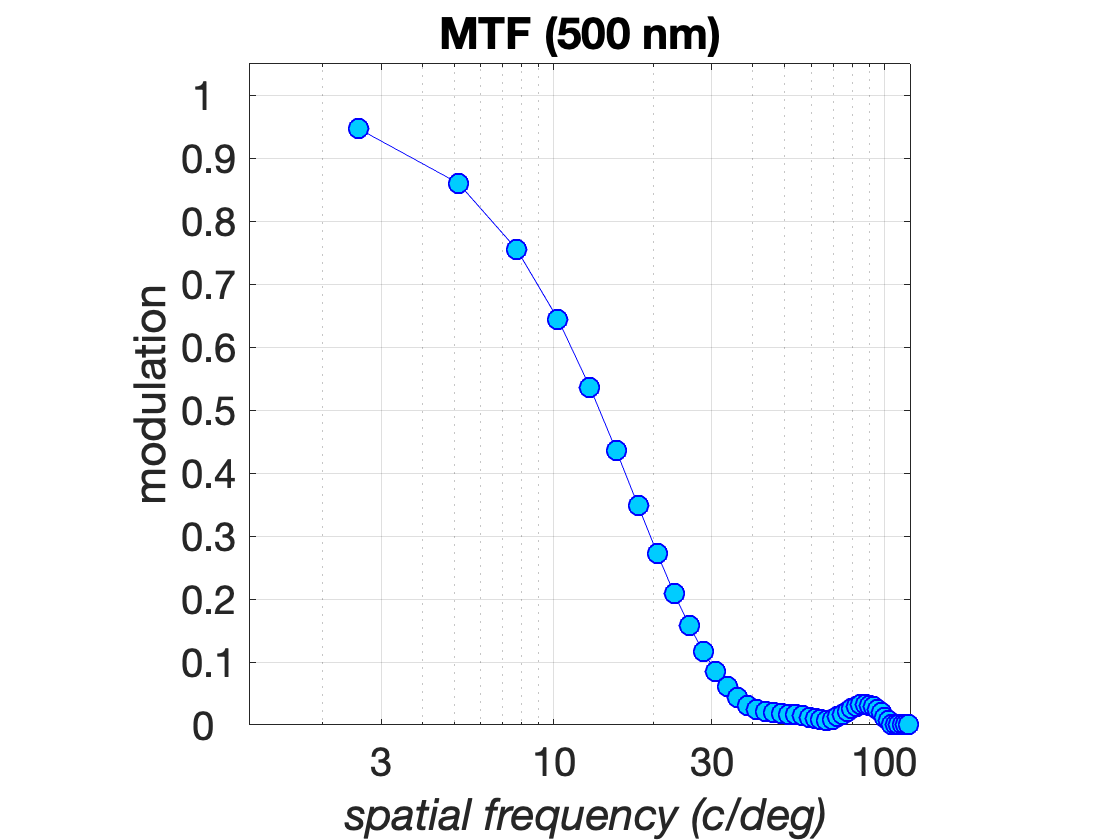

visualizeOTF(theOI, 500, visualizedSpatialSfrequencyCPD);

### Step 2.2 Generate the retinal optical image by passing the scene though the optics

Also visualize the retinal image.

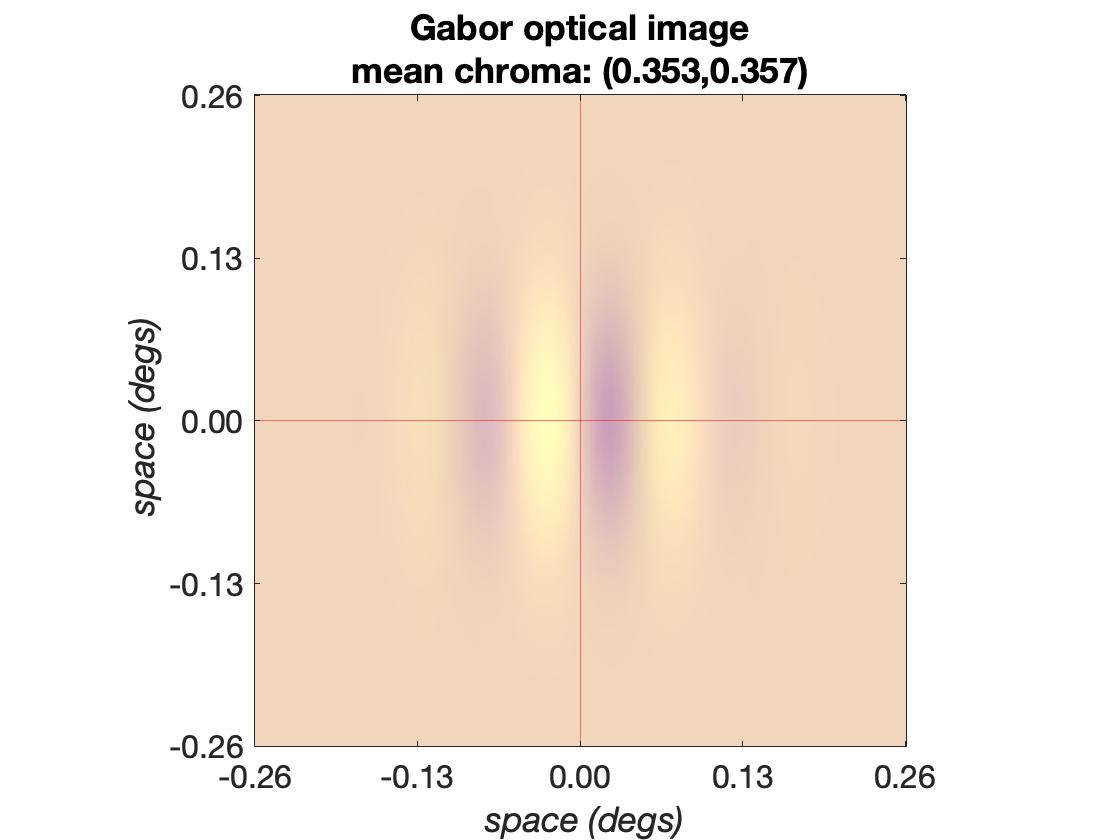

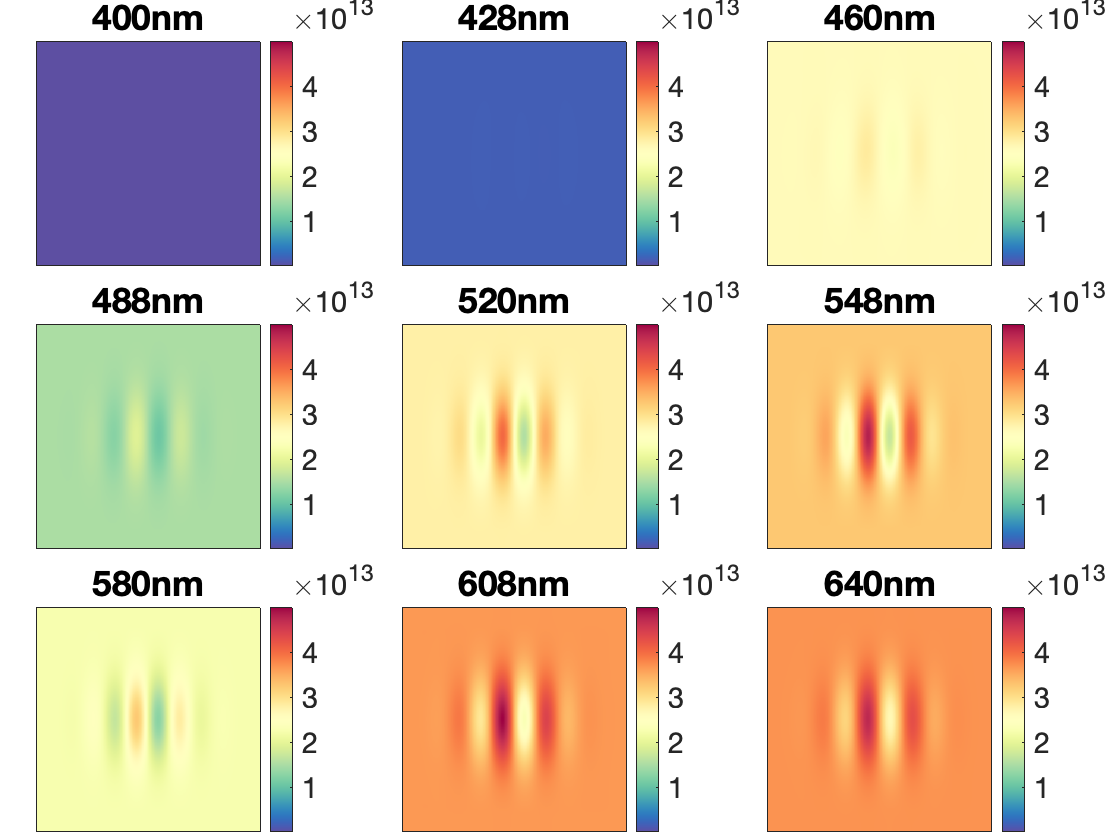

%% Compute the retinal image
theOI = oiCompute(theOI, realizedStimulusScene);

%% Visualize different aspects of the computed optical image
visualizeOpticalImage(theOI);

Note that the chromaticity of the optical image is different from that of the scene - it is more yellowish. This is due to absorption of short wavelength light by the lens. 

# **Step 3.** Create a cone mosaic object and compute its isomerization response to the optical image for a 20 msec presentation

### Step 3.1 Generate the cone mosaic

We generate a hexagonal, eccentricity-varying cone mosaic, with an integration time of 20 mseconds, and then compute its excitation response to the retinal image generated previously.

%% Generate a hexagonal cone mosaic with ecc-based cone quantal efficiency
theMosaic = coneMosaicHex(7, ...              % hex lattice sampling factor
   'fovDegs', stimParams.sizeDegs, ...        % match mosaic width to stimulus size
   'eccBasedConeDensity', true, ...           % cone density varies with eccentricity
   'eccBasedConeQuantalEfficiency', true, ... % cone quantal efficiency varies with eccentricity
   'integrationTime', 20/1000, ...            % 50 msec integration time
   'maxGridAdjustmentIterations', 50);        % terminate iterative lattice adjustment after 50 iterations


Hex grid adjustment: on iteration 0 ... 
Hex grid adjustment: on iteration 1 ... 
Hex grid adjustment: on iteration 2 ... 
Hex grid adjustment: on iteration 3 ... 
Hex grid adjustment: on iteration 4 ... 
Hex grid adjustment: on iteration 5 ... 
Hex grid adjustment: on iteration 6 ... 
Hex grid adjustment: on iteration 7 ... 
Hex grid adjustment: on iteration 8 ... 
Hex grid adjustment: on iteration 9 ... 
Hex grid adjustment: on iteration 10 ... 
Hex grid adjustment: on iteration 11 ... 
Hex grid adjustment: on iteration 12 ... 
Hex grid adjustment: on iteration 13 ... 
Hex grid adjustment: on iteration 14 ... 
Hex grid adjustment: on iteration 15 ... 
Hex grid adjustment: on iteration 16 ... 
Hex grid adjustment: on iteration 17 ... 
Hex grid adjustment: on iteration 18 ... 
Hex grid adjustment: on iteration 19 ... 
Hex grid adjustment: on iteration 20 ... 
Hex grid adjustment: on iteration 21 ... 
Hex grid adjustment: on iteration 22 ... 
Hex grid adjustment: on iteration 23 ... 
H

### Step 3.2 Compute mosaic responses to the optical image

Compute 50 responses instances asumming no fixational eye movements.

%% Compute mosaic responses to a number of stimulus presentations under zero eye movements
nTrialsNum = 50;   % generate 50 response instances
eyeMovementPath = zeros(nTrialsNum, 1, 2);
coneExcitations = theMosaic.compute(theOI, ...
    'emPath', eyeMovementPath);

### Step 3.3 Visualize results. 

We are visualizing the cone mosaic on the left, along with the first two response instances. All computed responses instances for cones located along the horizontal meridian are visualized on the bottom plot.

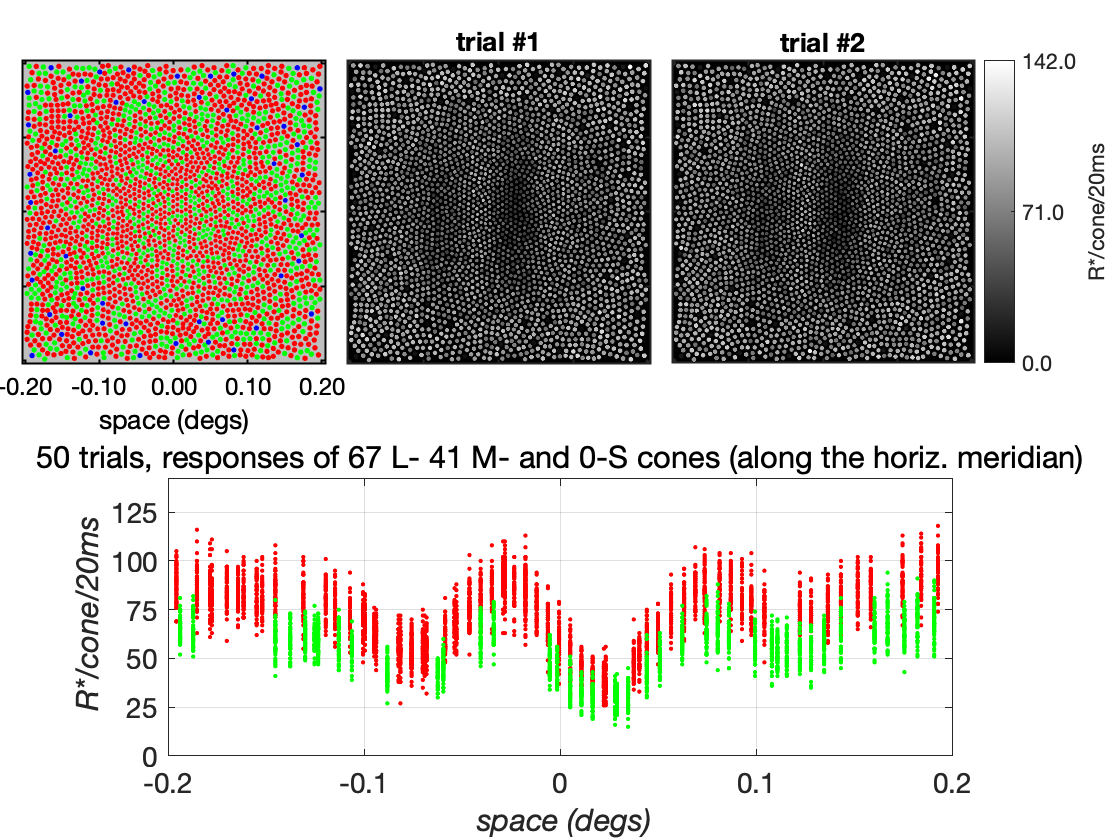

%% Visualize cone mosaic and its response
visualizeConeMosaicResponses(theMosaic, coneExcitations);

*Note that cone excitation levels are higher as we move away from the fovea. This is because cone aperture diameter increases with eccentricity, thereby allowing more photons to be absorbed.*